load('/lampllab/Ana ex extract/Ben.mat')
aluminum = Ben(15)

aluminum = struct with fields:
    channel_1: [1×21780000 double]
    channel_2: [1×21780000 double]
    channel_3: [1×21780000 double]


leaf = Ben (9)

leaf = struct with fields:
    channel_1: [1×20700000 double]
    channel_2: [1×20700000 double]
    channel_3: [1×20700000 double]


green = Ben (10)

green = struct with fields:
    channel_1: [1×18000000 double]
    channel_2: [1×18000000 double]
    channel_3: [1×18000000 double]


wrap = Ben (14)

wrap = struct with fields:
    channel_1: [1×14400000 double]
    channel_2: [1×14400000 double]
    channel_3: [1×14400000 double]


noObject = Ben (8)

noObject = struct with fields:
    channel_1: [1×18900000 double]
    channel_2: [1×18900000 double]
    channel_3: [1×18900000 double]


clear Ben

windowLength = 5 %Sec   

[b,a] = butter(2,[1,100]/30000,"bandpass")

b = 	1.0e+-4 *

    0.2667         0   -0.5335         0    0.2667


a =     1.0000   -3.9853    5.9561   -3.9562    0.9854


aluminum.filtered = filtfilt(b,a,aluminum.channel_1)

aluminum = struct with fields:
    channel_1: [1×21780000 double]
    channel_2: [1×21780000 double]
    channel_3: [1×21780000 double]
     filtered: [1×21780000 double]


leaf.filtered = filtfilt(b,a,leaf.channel_1)

leaf = struct with fields:
    channel_1: [1×20700000 double]
    channel_2: [1×20700000 double]
    channel_3: [1×20700000 double]
     filtered: [1×20700000 double]


green.filtered = filtfilt(b,a,green.channel_1)

green = struct with fields:
    channel_1: [1×18000000 double]
    channel_2: [1×18000000 double]
    channel_3: [1×18000000 double]
     filtered: [1×18000000 double]


wrap.filtered = filtfilt(b,a,wrap.channel_1)

wrap = struct with fields:
    channel_1: [1×14400000 double]
    channel_2: [1×14400000 double]
    channel_3: [1×14400000 double]
     filtered: [1×14400000 double]


noObject.filtered = filtfilt(b,a,noObject.channel_1)

noObject = struct with fields:
    channel_1: [1×18900000 double]
    channel_2: [1×18900000 double]
    channel_3: [1×18900000 double]
     filtered: [1×18900000 double]


figure;
plot((noObject.filtered))
hold on
plot(noObject.channel_3)


alumLim = [5922125:9618052]

alumLim =      5922125     5922126     5922127     5922128     5922129     5922130     5922131     5922132     5922133     5922134     5922135     5922136     5922137     5922138     5922139     5922140     5922141     5922142     5922143     5922144     5922145     5922146     5922147     5922148     5922149     5922150     5922151     5922152     5922153     5922154     5922155     5922156     5922157     5922158     5922159     5922160     5922161     5922162     5922163     5922164     5922165     5922166     5922167     5922168     5922169     5922170     5922171     5922172     5922173     5922174


leafLim = 1990076:4987843

leafLim =      1990076     1990077     1990078     1990079     1990080     1990081     1990082     1990083     1990084     1990085     1990086     1990087     1990088     1990089     1990090     1990091     1990092     1990093     1990094     1990095     1990096     1990097     1990098     1990099     1990100     1990101     1990102     1990103     1990104     1990105     1990106     1990107     1990108     1990109     1990110     1990111     1990112     1990113     1990114     1990115     1990116     1990117     1990118     1990119     1990120     1990121     1990122     1990123     1990124     1990125


greenLim = 1538165:7088506

greenLim =      1538165     1538166     1538167     1538168     1538169     1538170     1538171     1538172     1538173     1538174     1538175     1538176     1538177     1538178     1538179     1538180     1538181     1538182     1538183     1538184     1538185     1538186     1538187     1538188     1538189     1538190     1538191     1538192     1538193     1538194     1538195     1538196     1538197     1538198     1538199     1538200     1538201     1538202     1538203     1538204     1538205     1538206     1538207     1538208     1538209     1538210     1538211     1538212     1538213     1538214


noLim = 8778802:13387097

noLim =      8778802     8778803     8778804     8778805     8778806     8778807     8778808     8778809     8778810     8778811     8778812     8778813     8778814     8778815     8778816     8778817     8778818     8778819     8778820     8778821     8778822     8778823     8778824     8778825     8778826     8778827     8778828     8778829     8778830     8778831     8778832     8778833     8778834     8778835     8778836     8778837     8778838     8778839     8778840     8778841     8778842     8778843     8778844     8778845     8778846     8778847     8778848     8778849     8778850     8778851


cd('/lampllab/Data/M#3 headfixed awake natural object test/07_10_18 AeakeHeadRest')
avi = audioread('ch1B00259.WAV')

avi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%SPL = importdata('ch1B00251.txt')

figure; plot(avi)

thrExp = 3
thrAvi = 0.05

alumAviLim = [16046625:24467181]

alumAviLim =     16046625    16046626    16046627    16046628    16046629    16046630    16046631    16046632    16046633    16046634    16046635    16046636    16046637    16046638    16046639    16046640    16046641    16046642    16046643    16046644    16046645    16046646    16046647    16046648    16046649    16046650    16046651    16046652    16046653    16046654    16046655    16046656    16046657    16046658    16046659    16046660    16046661    16046662    16046663    16046664    16046665    16046666    16046667    16046668    16046669    16046670    16046671    16046672    16046673    16046674


leafAviLim = 6782502:14282502

leafAviLim =      6782502     6782503     6782504     6782505     6782506     6782507     6782508     6782509     6782510     6782511     6782512     6782513     6782514     6782515     6782516     6782517     6782518     6782519     6782520     6782521     6782522     6782523     6782524     6782525     6782526     6782527     6782528     6782529     6782530     6782531     6782532     6782533     6782534     6782535     6782536     6782537     6782538     6782539     6782540     6782541     6782542     6782543     6782544     6782545     6782546     6782547     6782548     6782549     6782550     6782551


greenAviLim = 4637228:20267206

greenAviLim =      4637228     4637229     4637230     4637231     4637232     4637233     4637234     4637235     4637236     4637237     4637238     4637239     4637240     4637241     4637242     4637243     4637244     4637245     4637246     4637247     4637248     4637249     4637250     4637251     4637252     4637253     4637254     4637255     4637256     4637257     4637258     4637259     4637260     4637261     4637262     4637263     4637264     4637265     4637266     4637267     4637268     4637269     4637270     4637271     4637272     4637273     4637274     4637275     4637276     4637277


noAviLim = 10220739:16829767

noAviLim =     10220739    10220740    10220741    10220742    10220743    10220744    10220745    10220746    10220747    10220748    10220749    10220750    10220751    10220752    10220753    10220754    10220755    10220756    10220757    10220758    10220759    10220760    10220761    10220762    10220763    10220764    10220765    10220766    10220767    10220768    10220769    10220770    10220771    10220772    10220773    10220774    10220775    10220776    10220777    10220778    10220779    10220780    10220781    10220782    10220783    10220784    10220785    10220786    10220787    10220788


expLim = alumLim
aviLim = alumAviLim
expstruct = aluminum

exp = resample(expstruct.channel_3(expLim),75000,60000)


[~,Iexp] = max(abs(exp))
[~,Iavi] = max(abs(avi(aviLim)))

sampDiff = Iexp - Iavi
sampDiff = floor(sampDiff/75000 * 60000)

expLim = expLim + sampDiff

expLim = [expLim,[expLim(end):expLim(end)+900000]]

figure; plot([1:length(expLim)]/60000,expstruct.channel_3(expLim)/100)
hold on
%plot([1:length(aviLim)]/75000,avi(aviLim))
%xlim([42 53])

AviLimTime = aviLim / 75000

[~,SPLstart] = min(abs(AviLimTime(1) - SPL(:,1))) 
[~,SPLend] = min(abs(AviLimTime(end)-SPL(:,1)))

SPLLim= SPLstart:SPLend

%windowsss =  11 

figure; plot([1:length(expLim)]/60000,envelope(expstruct.filtered(expLim))+15)
hold on
plot(SPL(SPLLim,1)-SPL(SPLLim(1),1),SPL(SPLLim,2))
xlim([23 34])
ylim([10 50])

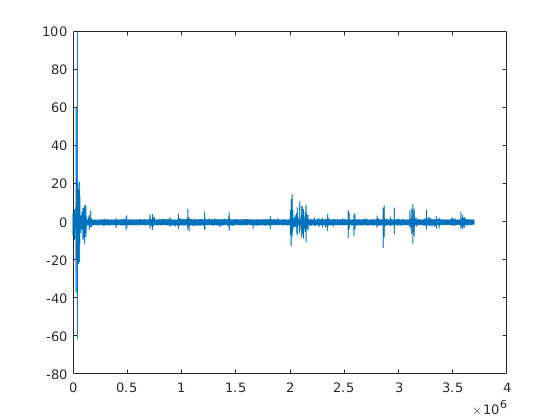

figure;
plot(aluminum.channel_3(alumLim))

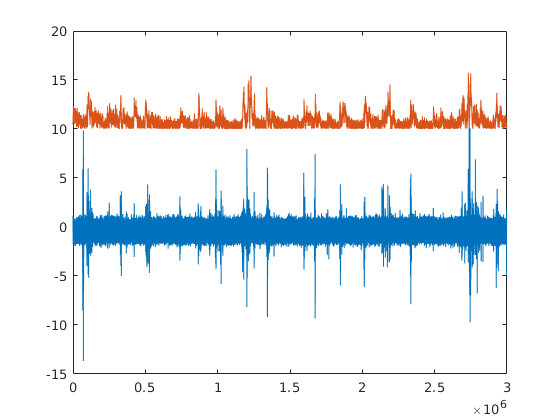

figure;
plot(leaf.channel_3(leafLim))
hold on 
plot(envelope(leaf.filtered(leafLim))+10)

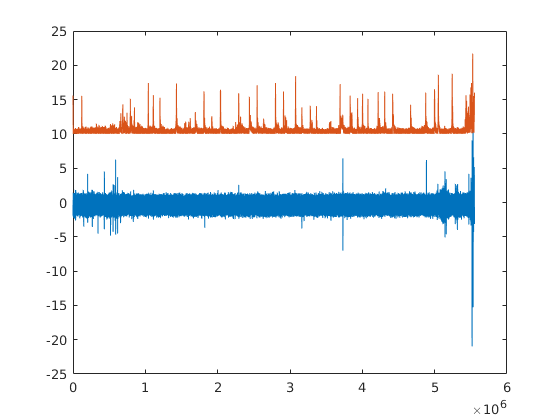

figure;
plot(green.channel_3(greenLim))
hold on
plot(envelope(green.filtered(greenLim))+10)

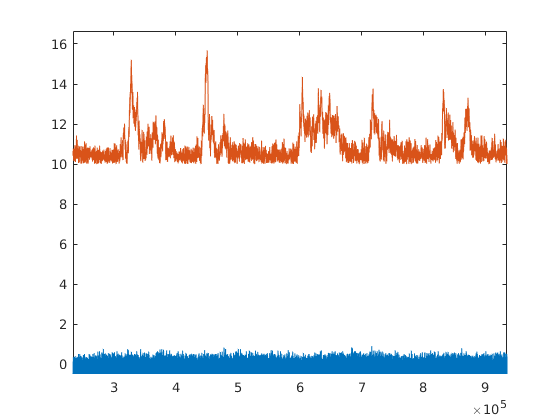

figure;
plot(noObject.channel_3(noLim))
hold on
plot(envelope(noObject.filtered(noLim))+10)

alum = aluminum.channel_3(alumLim)

alum =    -2.3041   -2.3956   -1.2665   -0.2899   -0.0153   -0.0153    0.4120    0.7477    0.7172    0.7019    2.4719    3.8452    4.1504    4.1809    1.6327   -0.4578   -0.9766   -1.1292   -0.5646    0.1831    0.2747    0.2747    0.3662    0.4730    0.5188    0.4425    2.3804    3.9063    4.2267    4.2877    0.1678   -3.2349   -4.1046   -4.2877   -2.6855   -1.2054   -0.8698   -0.7477   -0.3357    0.1526    0.2289    0.1678    0.1526    0.0916    0.0916    0.1373   -1.9531   -3.9215   -4.3793   -4.3793


alum = alum(2511521:3239631)

alum =    -0.4578   -0.3357   -0.2136    0.0305         0    0.0916   -0.0458   -0.7935   -0.9766   -0.8545   -1.0223   -0.5341   -0.5341   -0.5493   -0.3967   -0.4883   -0.3967   -0.3967   -0.4120   -0.4425   -0.5188   -0.3052   -0.4425   -0.6409   -0.4883   -0.5951   -0.5341   -0.6561   -0.6409   -0.5341   -0.6256   -0.3357   -0.3357   -0.3052   -0.3662   -0.5951   -0.5798   -0.5951   -0.2441    0.2747    0.2747    0.4425    0.0305   -0.1678   -0.2136   -0.3204   -0.2441   -0.1221   -0.1373   -0.1984


noObj = noObject.channel_3(noLim)

noObj =    -0.7782   -0.9766   -0.3815   -0.1068   -0.0305         0    0.1678    0.0763    0.0458   -0.1221   -0.3052   -0.4120   -0.3510   -0.3510   -0.3662   -0.3357   -0.5035   -0.5188   -0.3052   -0.2136   -0.2289   -0.2289   -0.1831   -0.1373         0    0.0153   -0.4883   -0.8087   -0.6866   -0.7324   -0.7782   -0.6866   -0.6561   -0.5646   -0.0458    0.1068    0.0305    0.0458    0.1984    0.1373    0.0610    0.2441    0.0305   -0.1678   -0.2594   -0.4120   -0.4730   -0.3967   -0.3052   -0.4425


noObj = noObj(233982:934890)

noObj =    -0.5798   -0.5951   -0.4425   -0.4730   -0.5798   -0.4730   -0.3510   -0.3357   -0.4730   -0.6409   -0.2747   -0.2289   -0.3204   -0.3357   -0.2136   -0.0305   -0.1984   -0.2441   -0.2136   -0.2747   -0.2441   -0.0916   -0.0763   -0.2136   -0.3357   -0.3662   -0.5341   -0.6561   -0.6256   -0.5493   -0.3662   -0.3662   -0.4730   -0.3967   -0.0763   -0.1678   -0.2594   -0.3052   -0.2136   -0.1678   -0.3052   -0.2594   -0.4883   -0.5493   -0.6256   -0.7935   -0.8392   -0.7477   -0.7629   -0.8240


gre = green.channel_3(greenLim)

gre =    -0.4578   -0.3815   -0.6256   -0.8087   -0.9003   -0.7935   -0.7629   -0.6714   -0.7629   -0.8698   -0.2594   -0.0610   -0.0305   -0.1068   -0.8392   -0.9155   -0.9308   -0.9308    0.0763    0.1984    0.4120    0.4578    0.0458   -0.2136   -0.0763    0.0763   -0.1984   -0.4120   -0.5493   -0.5341   -0.1678   -0.0610   -0.1373   -0.1373   -0.0153   -0.0610   -0.1221   -0.1373   -0.0305   -0.0916   -0.1068   -0.0610    0.0305    0.1678         0   -0.0153   -0.1221   -0.2441   -0.3204   -0.3052


gre = gre(3484442:4170266)

gre =    -0.1373   -0.1678   -0.3052   -0.0153    0.1068    0.0763   -0.0458   -0.4883   -0.6561   -0.7629   -0.6866   -0.4425   -0.4883   -0.3967   -0.3662   -0.2289   -0.0916         0   -0.0153   -0.7935   -1.1139   -1.3428   -1.4496   -0.8392   -0.6561   -0.6561   -0.5188   -0.8545   -0.9918   -1.0529   -0.9155   -0.0458    0.0763    0.1373    0.1373   -0.8698   -1.1902   -1.3885   -1.3885    0.0153    0.6104    0.7019    0.5646   -0.8392   -1.2054   -1.2512   -1.3123   -0.6561   -0.3357   -0.3662


lea = leaf.channel_3(leafLim)

lea =    -0.3967   -0.5493   -0.6256   -0.5188   -0.3662   -0.5035   -0.5035   -0.4578   -0.9918   -1.3275   -1.2817   -1.3123   -1.0986   -0.8850   -0.8087   -0.9155   -0.5646   -0.4578   -0.4578   -0.3204   -0.2289   -0.3052   -0.4425   -0.3204   -0.6714   -0.9155   -0.8850   -0.8545   -0.7477   -0.6409   -0.6104   -0.6561   -0.6409   -0.5798   -0.6714   -0.6104   -0.5035   -0.4578   -0.5035   -0.5951   -0.7324   -0.7782   -0.7324   -0.8240   -0.3967   -0.1068    0.0916    0.0153   -0.5493   -0.6714


lea = lea(2163554:2819067)

lea =     0.0305    0.0916   -0.2594   -0.5493   -0.5035   -0.4730   -0.7172   -0.9766   -1.0529   -0.9155   -0.8392   -0.7629   -0.8240   -0.7324   -0.6714   -0.5798   -0.5035   -0.5188   -0.6256   -0.8240   -0.8850   -0.8545   -0.5798   -0.1221   -0.0458   -0.0153    0.0153   -0.1984   -0.1678   -0.1678   -0.2899   -0.5798   -0.5341   -0.6561   -0.7782   -1.0223   -0.9155   -0.9155   -0.8392   -0.6104   -0.4730   -0.4578   -0.4730   -0.5341   -0.5188   -0.5493   -0.5035   -0.3815   -0.3967   -0.3052


2511521/60000

ans = 41.8587

2163554/60000

ans = 36.0592

figure;

spectrogram(alum,50,40,300,60000)

[b,a] = butter(3,[22000,23000]/30000,'stop')

b =     0.9005    3.8259    8.1196   10.2094    8.1196    3.8259    0.9005


a =     1.0000    4.1002    8.3980   10.1954    7.8314    3.5655    0.8110


alum = filtfilt(b,a,alum)

alum =    -0.4843   -0.3520   -0.1167    0.0491    0.0342    0.1152   -0.1373   -0.8193   -1.0198   -0.8874   -0.9386   -0.4996   -0.4802   -0.5052   -0.4704   -0.5327   -0.4625   -0.4537   -0.3503   -0.3870   -0.4399   -0.2338   -0.4908   -0.7082   -0.5811   -0.6820   -0.5002   -0.5765   -0.5339   -0.4310   -0.6445   -0.4276   -0.4566   -0.4244   -0.3624   -0.4914   -0.4456   -0.4602   -0.2332    0.1602    0.1285    0.2931    0.0056   -0.0441   -0.0572   -0.1582   -0.2065   -0.2533   -0.3019   -0.3713


lea = filtfilt(b,a,lea)

lea =     0.0047    0.0623   -0.2657   -0.5171   -0.4656   -0.4313   -0.7064   -1.0190   -1.1045   -0.9715   -0.8553   -0.7093   -0.7571   -0.6607   -0.6493   -0.6453   -0.5868   -0.6077   -0.6543   -0.7462   -0.7842   -0.7473   -0.5440   -0.2124   -0.1648   -0.1416   -0.0281   -0.0956   -0.0302   -0.0218   -0.2385   -0.6947   -0.6905   -0.8219   -0.8378   -0.8960   -0.7405   -0.7304   -0.7714   -0.7473   -0.6658   -0.6613   -0.5490   -0.3878   -0.3093   -0.3288   -0.4197   -0.5357   -0.6213   -0.5406


gre= filtfilt(b,a,gre)

gre =    -0.2643   -0.3002   -0.3921    0.0831    0.2627    0.2424    0.0791   -0.5987   -0.8424   -0.9645   -0.8520   -0.3203   -0.2709   -0.1589   -0.1589   -0.3624   -0.3400   -0.2737   -0.2646   -0.6496   -0.8354   -1.0348   -1.1597   -0.9922   -0.9626   -0.9956   -0.8463   -0.6942   -0.6603   -0.6858   -0.5546   -0.2115   -0.2763   -0.2523   -0.2516   -0.7010   -0.8211   -0.9820   -0.9780   -0.1540    0.2302    0.2847    0.1394   -0.6721   -0.8199   -0.8298   -0.8798   -0.8186   -0.7209   -0.7854


noObj = filtfilt(b,a,noObj)

noObj =    -0.5862   -0.5662   -0.4358   -0.4278   -0.5738   -0.5017   -0.3583   -0.3816   -0.4782   -0.6128   -0.2668   -0.1832   -0.3166   -0.3626   -0.2218   -0.0752   -0.2003   -0.2187   -0.2054   -0.2319   -0.2445   -0.1153   -0.0842   -0.2536   -0.3325   -0.3445   -0.5267   -0.6196   -0.6320   -0.5689   -0.3727   -0.3987   -0.4632   -0.3794   -0.0709   -0.1398   -0.2728   -0.3202   -0.2178   -0.1912   -0.2883   -0.2467   -0.4853   -0.5305   -0.6457   -0.8037   -0.8410   -0.7622   -0.7401   -0.8163


[pxxAlum,f] = pspectrum(alum,60000)

pxxAlum =     0.2895
    0.2759
    0.2388
    0.1875
    0.1334
    0.0859
    0.0499
    0.0263
    0.0126
    0.0057


f = 	1.0e+04 *

         0
    0.0007
    0.0015
    0.0022
    0.0029
    0.0037
    0.0044
    0.0051
    0.0059
    0.0066


[pxxLeaf,f] = pspectrum(lea,60000)

pxxLeaf =     0.2938
    0.2800
    0.2424
    0.1903
    0.1355
    0.0872
    0.0507
    0.0267
    0.0128
    0.0058


f = 	1.0e+04 *

         0
    0.0007
    0.0015
    0.0022
    0.0029
    0.0037
    0.0044
    0.0051
    0.0059
    0.0066


[pxxgre,f] = pspectrum(gre,60000)

pxxgre =     0.2928
    0.2790
    0.2415
    0.1897
    0.1349
    0.0868
    0.0505
    0.0265
    0.0126
    0.0056


f = 	1.0e+04 *

         0
    0.0007
    0.0015
    0.0022
    0.0029
    0.0037
    0.0044
    0.0051
    0.0059
    0.0066


[pxxnon,f] = pspectrum(noObj,60000)

pxxnon =     0.2881
    0.2746
    0.2377
    0.1866
    0.1328
    0.0855
    0.0497
    0.0261
    0.0125
    0.0056


f = 	1.0e+04 *

         0
    0.0007
    0.0015
    0.0022
    0.0029
    0.0037
    0.0044
    0.0051
    0.0059
    0.0066


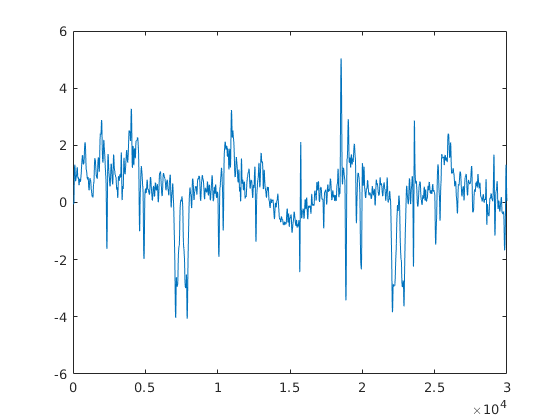

figure;
plot(f,pow2db(pxxAlum)-pow2db(pxxgre))


aviAlum = avi(alumAviLim);

aviLeaf = avi(leafAviLim)

aviLeaf =    -0.0009
    0.0009
   -0.0030
    0.0044
   -0.0014
    0.0047
   -0.0032
    0.0006
    0.0005
   -0.0046


figure;
ax = subplot(2,1,1)

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


spectrogram(aviAlum,300,260,2000,150000,'yaxis')
colormap('bone')
caxis([-100 -60])
title('Whsiking against aluminum spectral profile')
%xlim([47.2 48.2])
bx = subplot(2,1,2)

bx =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


spectrogram(aviLeaf,300,260,2000,150000,'yaxis')
colormap('bone')
caxis([-100 -60])
title('Whsiking against a dry leaf spectral profile')

%xlim([38.4 39.4])